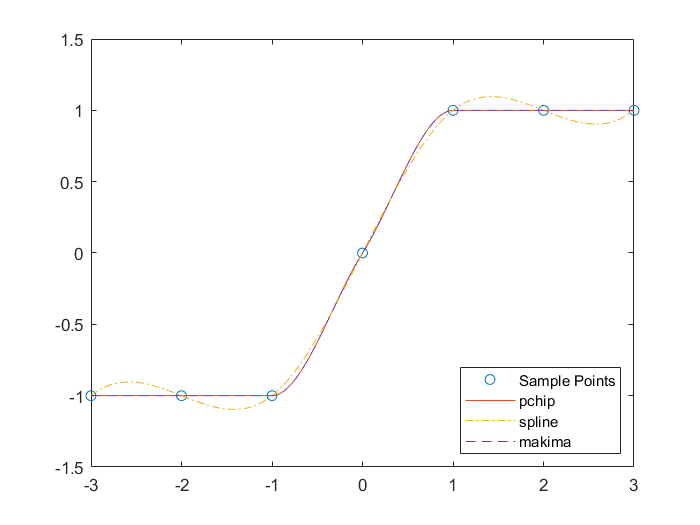

x = -3:3; 
y = [-1 -1 -1 0 1 1 1]; 
xq1 = -3:.01:3;
p = pchip(x,y,xq1);
s = spline(x,y,xq1);
m = makima(x,y,xq1);
plot(x,y,'o',xq1,p,'-',xq1,s,'-.',xq1,m,'--')
legend('Sample Points','pchip','spline','makima','Location','SouthEast')

esempio mio

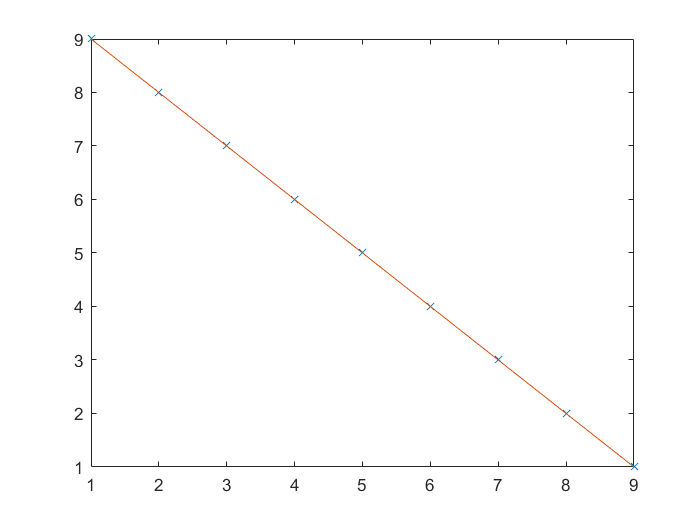

tempo = 1:0.1:9;
x_coord = [1 2 3 4 5 6 7 8 9]';
y_coord = [9 8 7 6 5 4 3 2 1]';
S=spline(x_coord,y_coord,tempo);
figure,
plot(x_coord,y_coord,'x',S,tempo)

cerchio prova

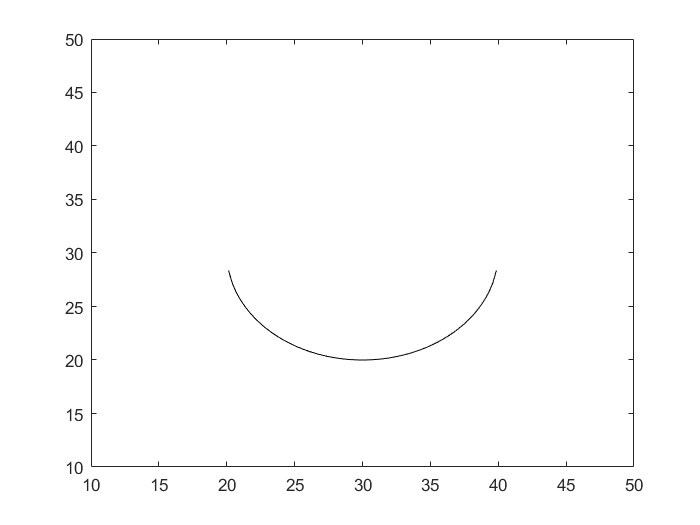

Xc=30;
Yc=30;
r=10;

cerchio_neg=@(x,y)(y-Yc)+sqrt(r^2-(x-Xc).^2);
cerchio_pos=@(x,y)(y-Yc)-sqrt(r^2-(x-Xc).^2);

fimplicit(cerchio_neg,[10,50],'k')

fimplicit(cerchio_pos,[10,50],'b','linewidth',2)
hold on
yline(Yc)
xline(Xc)
grid on
axis equal

cerchio 2

close all

Xc=30;
Yc=30;
r=10;
 

cerchio =@(x,y) (y-Yc).^2+(x-Xc).^2-r^2;
c_neg = @(x,y)(y-Yc)+sqrt(r^2-(x-Xc).^2)

c_neg = function_handle with value:
    @(x,y)(y-Yc)+sqrt(r^2-(x-Xc).^2)


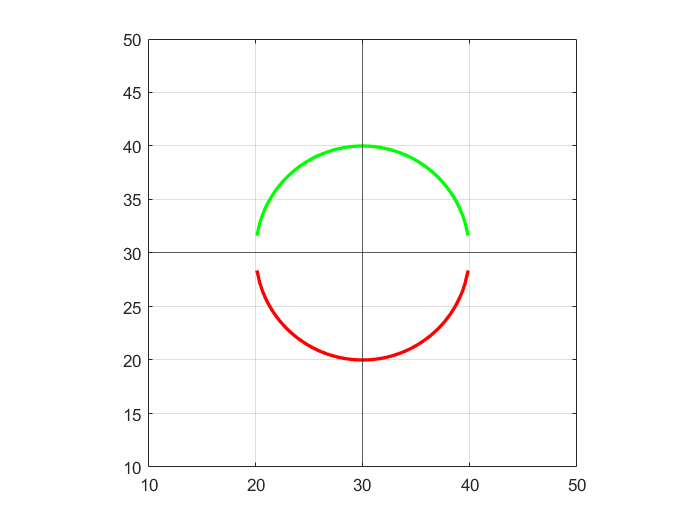

cerchio_pos=@(x,y)(y-Yc)-sqrt(r^2-(x-Xc).^2);
cerchio_pos_2=@(x,y)(y-Yc)-sqrt(r^2-(x-Xc).^2);

fimplicit(c_neg,[10,50],'r','linewidth',2)
hold on
fimplicit(cerchio_pos,[10,50],'g','linewidth',2)
hold on
%fimplicit(cerchio,[10,50],'k--')
hold on
yline(Yc)
xline(Xc)
grid on
axis equal

(x-x0)^2+(y-y0)^2=r^2

(y-y0)^2=r^2-(x-x0)^2

syms x 

y1=2*x+3;
y2=-1/2*(x-4)+6;
X =vpasolve(y1==y2,x)

$$X = 2.0$$

Y=subs(y1,x,X)

$$Y = 7.0$$

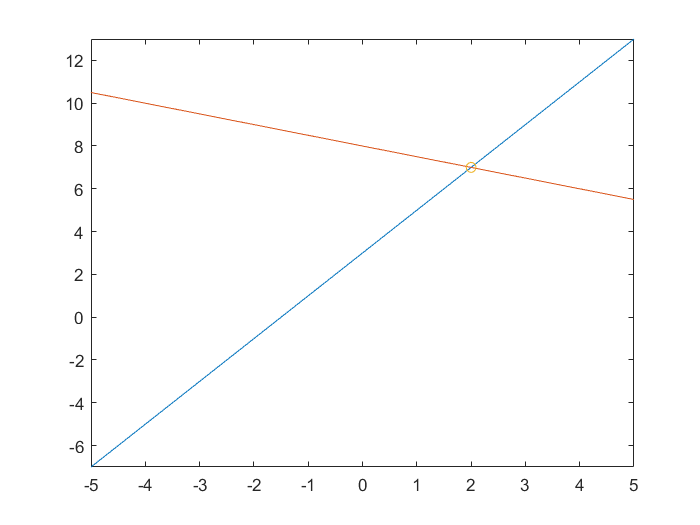

figure,
fplot(y1)
hold on
fplot(y2)
scatter(X,Y,'o')

esempio

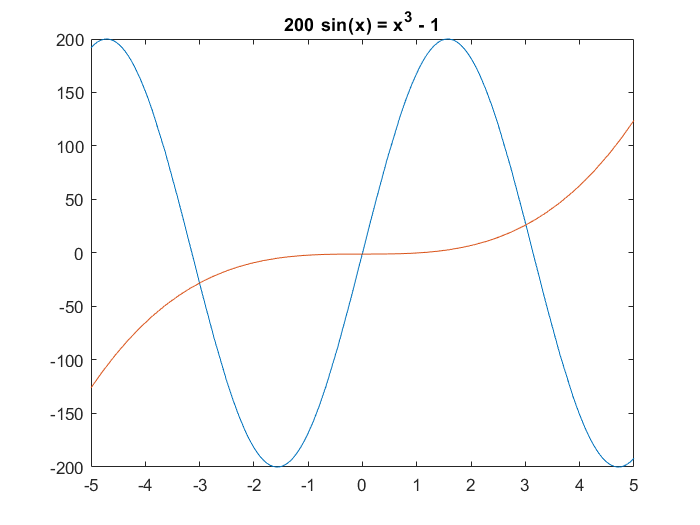

syms x
eqnLeft = 200*sin(x);
eqnRight = x^3 - 1;
fplot([eqnLeft eqnRight])
title([texlabel(eqnLeft) ' = ' texlabel(eqnRight)])

S1 = vpasolve(eqnLeft == eqnRight, x)

$$S1 = -0.0050000214585835715725440675982988$$